# Channel Modelling

The 5G Toolbox includes two fading channel models:

- TDL channel model (2D model)

- CDL channel model (3D model)

## TDL Channel

The TDL channel is a 2D Rayleigh fading channel model.

### Create channel

Create a TDL channel instance.

tdlchannel = nrTDLChannel()

tdlchannel =   nrTDLChannel with properties:

                 DelayProfile: 'TDL-A'
                  DelaySpread: 3.0000e-08
          MaximumDopplerShift: 5
                   SampleRate: 30720000
              MIMOCorrelation: 'Low'
                 Polarization: 'Co-Polar'
        TransmissionDirection: 'Downlink'
          NumTransmitAntennas: 1
           NumReceiveAntennas: 2
           NormalizePathGains: true
                  InitialTime: 0
                 NumSinusoids: 48
                 RandomStream: 'mt19937ar with seed'
                         Seed: 73
      NormalizeChannelOutputs: true
    TransmitAndReceiveSwapped: false


tdlchannel.DelayProfile = 'TDL-B';
tdlchannel.DelaySpread = 100e-9;

### Create waveform to send through the channel

Generate a 5G waveform (one slot) with the PDSCH and its DM-RS and send it through the generated channel. 

carrier = nrCarrierConfig;
pdsch = nrPDSCHConfig;
[channelInput,waveformInfo] = pdshWaveform(carrier,pdsch,tdlchannel.NumTransmitAntennas);

### Send signal through the channel

Before sending a signal through the channel, set the channel sampling rate based on the waveform's sampling rate.

tdlchannel.SampleRate = waveformInfo.SampleRate;
[channelOutput,pathGains] = tdlchannel(channelInput);

Plot the spectrogram of the channel input and output

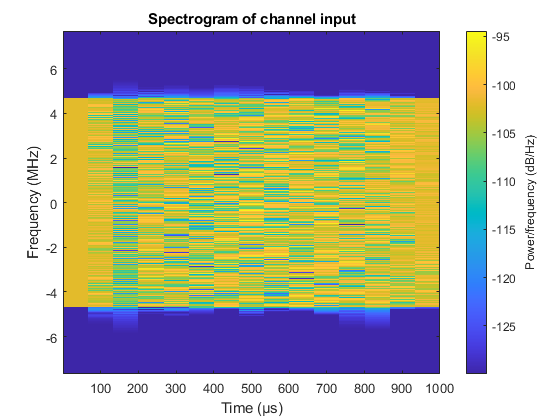

% Plot spectogram of waveform for first antenna port
sampleRate = waveformInfo.SampleRate;
nfft = waveformInfo.Nfft;
spectrogram(channelInput(:,1),ones(nfft,1),0,nfft,'centered',sampleRate,'yaxis','MinThreshold',-130);
title('Spectrogram of channel input');

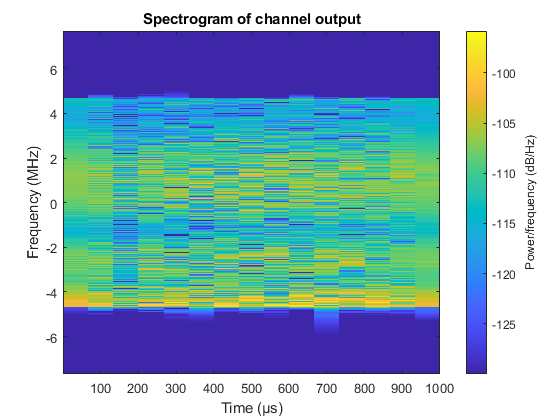

spectrogram(channelOutput(:,1),ones(nfft,1),0,nfft,'centered',sampleRate,'yaxis','MinThreshold',-130);
title('Spectrogram of channel output');

### Visualise the channel frequency response

The channel frequency response can be obtained using the perfect channel estimator.

Get the path filters used in channel filtering.

pathFilters = getPathFilters(tdlchannel);

Call the perfect channel estimator

hest = nrPerfectChannelEstimate(carrier,pathGains,pathFilters);
size(hest)

ans =    624    14     2


The returned matrix contains the channel response for every subcarrier, OFDM symbol and receive antenna. Plot the channel magnitude for both links between the transmit antenna and the receive antennas.

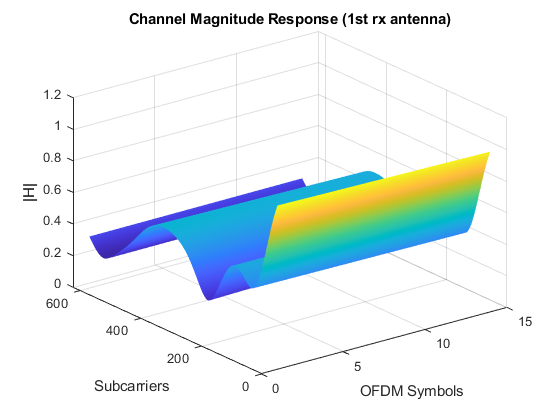

surf(abs(hest(:,:,1)));
shading('flat');
xlabel('OFDM Symbols');ylabel('Subcarriers');zlabel('|H|');
title('Channel Magnitude Response (1st rx antenna)');

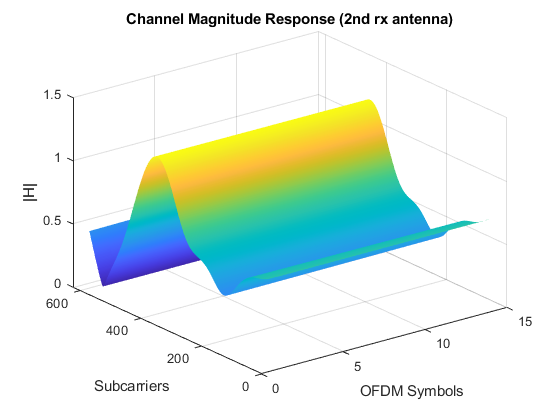

surf(abs(hest(:,:,2)));
shading('flat');
xlabel('OFDM Symbols');ylabel('Subcarriers');zlabel('|H|');
title('Channel Magnitude Response (2nd rx antenna)');

## CDL channel model

The CDL channel is a 3D Rayleigh fading channel model.

Create a CDL channel instance.

cdlChannel = nrCDLChannel()

cdlChannel =   nrCDLChannel with properties:

                 DelayProfile: 'CDL-A'
                 AngleScaling: false
                  DelaySpread: 3.0000e-08
             CarrierFrequency: 4.0000e+09
          MaximumDopplerShift: 5
          UTDirectionOfTravel: [2×1 double]
                   SampleRate: 30720000
         TransmitAntennaArray: [1×1 struct]
     TransmitArrayOrientation: [3×1 double]
          ReceiveAntennaArray: [1×1 struct]
      ReceiveArrayOrientation: [3×1 double]
           NormalizePathGains: true
                SampleDensity: 64
                  InitialTime: 0
                 RandomStream: 'mt19937ar with seed'
                         Seed: 73
             ChannelFiltering: true
      NormalizeChannelOutputs: true
    TransmitAndReceiveSwapped: false


Since the CDL channel is a 3D model, the antenna arrays are not limitted to linear arrays. The antenna arrays are specified via a structure. Display the transmit and receive antenna array fields.

cdlChannel.TransmitAntennaArray

ans = struct with fields:
                  Size: [2 2 2 1 1]
        ElementSpacing: [0.5000 0.5000 1 1]
    PolarizationAngles: [45 -45]
           Orientation: [3×1 double]
               Element: '38.901'
     PolarizationModel: 'Model-2'


Here the Size of antenna array is specified by vector [*M* *N* *P* *M*g *N*g], where:

- *M* and *N* are the number of rows and columns in each antenna panel, respectively.

- *P* is the number of polarizations (1 or 2).

- *M*g and *N*g are the number of rows and columns in the array of panels, respectively.

The Element Spacing, in wavelengths, is specified as a row vector of the form [*λ*v *λ*h *dg*v *dg*h]. The vector elements represent the vertical and horizontal element spacing and the vertical and horizontal panel spacing, respectively.

cdlChannel.ReceiveAntennaArray

ans = struct with fields:
                  Size: [1 1 2 1 1]
        ElementSpacing: [0.5000 0.5000 0.5000 0.5000]
    PolarizationAngles: [0 90]
           Orientation: [3×1 double]
               Element: 'isotropic'
     PolarizationModel: 'Model-2'


Note the size of these arrays and visualise them.

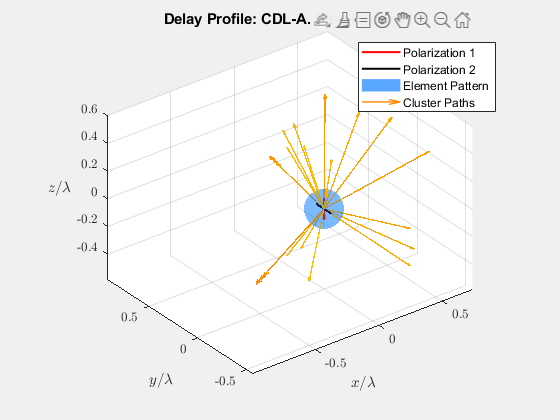

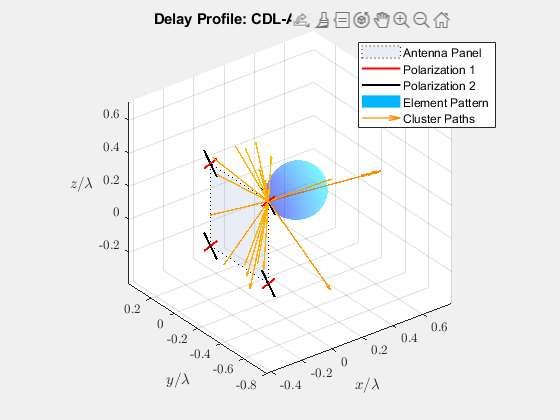

cdlChannel.displayChannel();

function [waveform,waveformInfo] = pdshWaveform(carrier,pdsch,nTxAnts)

% Generate an empty resource grid. This grid represents a slot
pdschGrid = nrResourceGrid(carrier,nTxAnts);

% Generate indices to map the PDSCH to the grid
[pdschIndices,pdschInfo] = nrPDSCHIndices(carrier,pdsch);

% Generate random PDSCH bits and map to PDSCH symbols. For simplicity, this example does not include the DL-SCH modeling.
pdschBits = randi([0 1],pdschInfo.G,1);

% Generate PDSCH symbols
pdschSymbols = nrPDSCH(carrier,pdsch,pdschBits);

% Precode the PDSCH symbols
precodingWeights = ones(pdsch.NumLayers,nTxAnts)/nTxAnts;
pdschSymbolsPrecoded = pdschSymbols*precodingWeights;

% Generate DM-RS symbols and indices
dmrsSymbols = nrPDSCHDMRS(carrier,pdsch);
dmrsIndices = nrPDSCHDMRSIndices(carrier,pdsch);

% Map the PDSCH symbols to the grid
[~,pdschAntIndices] = nrExtractResources(pdschIndices,pdschGrid);
pdschGrid(pdschAntIndices) = pdschSymbolsPrecoded;

% PDSCH DM-RS precoding and mapping
for p = 1:size(dmrsSymbols,2)
    [~,dmrsAntIndices] = nrExtractResources(dmrsIndices(:,p),pdschGrid);
    pdschGrid(dmrsAntIndices) = pdschGrid(dmrsAntIndices) + dmrsSymbols(:,p)*precodingWeights(p,:);
end

% Perform OFDM modulation of the resource grid
[waveform,waveformInfo] = nrOFDMModulate(carrier,pdschGrid);

end